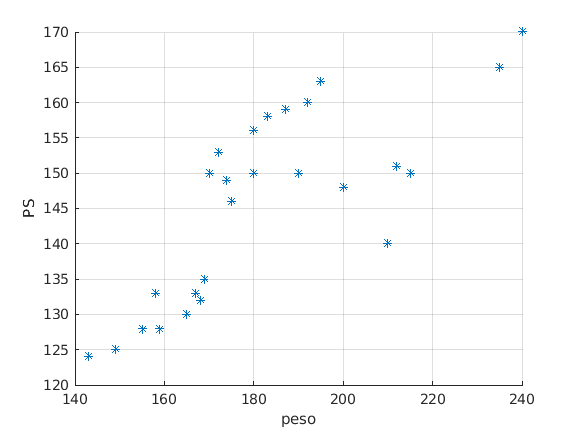

clc
clear
%%DECLARACION DE VARIABLES
peso=[165,167,180,155,212,175,190,210,200,149,158,169,170,172,159,168,174,183,215,195,180,143,240,235,192,187];
PS=[130,133,150,128,151,146,150,140,148,125,133,135,150,153,128,132,149,158,150,163,156,124,170,165,160,159];

%diagrama de dispersion
scatter(peso,PS,'*')
grid on
xlabel('peso')
ylabel('PS')


%matriz de covarianza y varianzas
v=cov(peso,PS)

v =   612.4938  256.8892
  256.8892  180.0862


covarianza=v(2,1)

covarianza = 256.8892

%coeficiente de correlacion
r=corrcoef(peso,PS)

r =     1.0000    0.7735
    0.7735    1.0000


coeficiente_correlacion=r(2,1)

coeficiente_correlacion = 0.7735


%regresion lineal
n=length(peso);
A=[n sum(peso); sum(peso) sum(peso.^2)];
c=[sum(PS); sum(peso.*PS)];
solucion=inv(A)*c;
bo=solucion(1);
b1=solucion(2);

syms xa
recta=bo+b1*xa

$$recta = \frac{59027442236395\,\mathrm{xa}}{140737488355328}+\frac{37990530707039}{549755813888}$$

xa=peso;

%coeficiente de determinacion
r2=sum((eval(recta)-mean(PS)).^2)/sum((PS-mean(PS)).^2)

r2 = 0.5983